clc
clear
close all

%% Data
Ts = 1;
s = tf('s');
H = 10000;
Gp = 100/(s^2+1.2*s+1);
Gd = c2d(Gp,1,'zoh')

Gd =
 
      32.24 z + 21.41
  -----------------------
  z^2 - 0.7647 z + 0.3012
 
Sample time: 1 seconds
Discrete-time transfer function.



u = rand(H,1);
w = lsim(Gd,u);
var = 25;
sigma = sqrt(var);
global theta_real
theta_real = [-0.7647 0.3012 0 32.2369 21.41]'

theta_real =    -0.7647
    0.3012
         0
   32.2369
   21.4100


A = zeros(5,5);
for k = 3:H
    A(k-2,:) = [-w(k-1) -w(k-2) u(k) u(k-1) u(k-2)];
end

theta =    -0.7647
    0.3012
    0.0000
   32.2369
   21.4103


Error between real theta and estimated theta is: 0.00035045
    "Relative error is: 0.00281123"
    "Relative error is: 0.00192171"
    "Relative error is: 100"
    "Relative error is: 6.9341e-05"
    "Relative error is: 0.0016302"



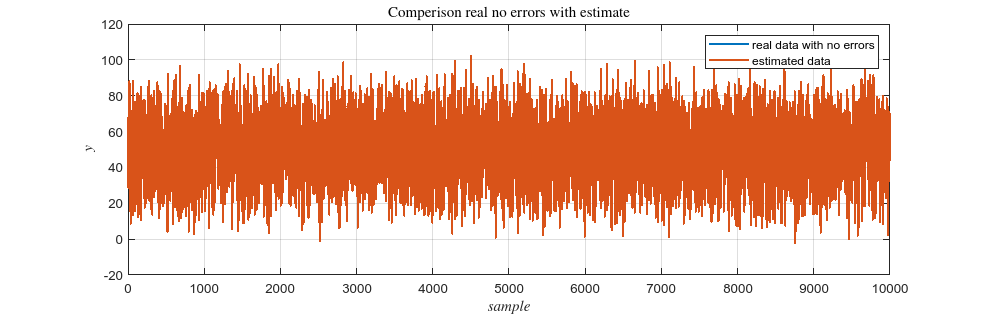

%% LS
str1 = 'real data with no errors';
str2 = 'estimated data';
mtitle = 'Comperison real no errors with estimate';
plot_result(A,w,u,str1,str2,mtitle,1,H);

theta =    -0.7762
    0.3116
    0.2078
   32.2405
   21.0843


Error between real theta and estimated theta is: 0.38668
    "Relative error is: 1.4787"
    "Relative error is: 3.32261"
    "Relative error is: 100"
    "Relative error is: 0.011124"
    "Relative error is: 1.54471"



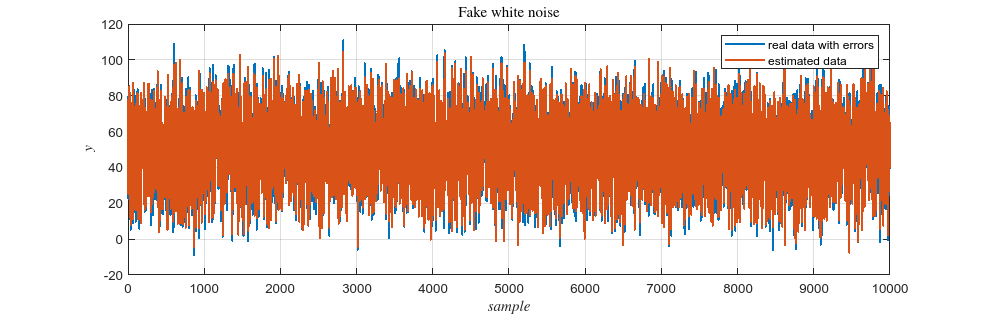


%% Errors added in a way that they depend on the plant
e = sigma.*randn(H,1);
De = tf(1,Gd.Denominator,Ts);
w1 = lsim(Gd,u);
w2 = lsim(De,e);
y = w1+w2; % new collected output taking into account errors
str1 = 'real data with errors';
str2 = 'estimated data';
mtitle = 'Fake white noise';
plot_result(A,y,u,str1,str2,mtitle,2,H);

theta =    -0.5369
    0.1352
   -0.2887
   32.0653
   28.1921


Error between real theta and estimated theta is: 6.7962
    "Relative error is: 42.43072"
    "Relative error is: 122.7078"
    "Relative error is: 100"
    "Relative error is: 0.5350078"
    "Relative error is: 24.05669"



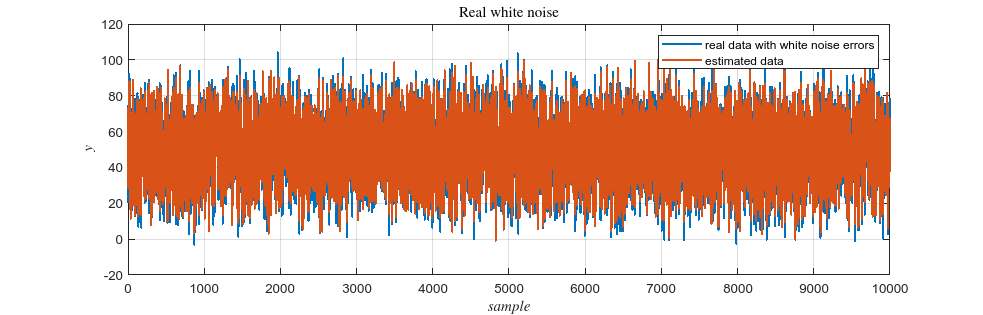


%% Errors put at the end of the process so that it's really a white guaussian noise

w = w1;
y = w + e;
str1 = 'real data with white noise errors';
str2 = 'estimated data';
mtitle = 'Real white noise';
plot_result(A,y,u,str1,str2,mtitle,3,H);

%% Functions

function plot_result(A,y,u,str1,str2,mtitle,no_fig,H)
    global theta_real
    figure(no_fig)
    b = y(3:end);
    for k = 3:H
        A(k-2,:) = [-y(k-1) -y(k-2) u(k) u(k-1) u(k-2)];
    end
    fig=gcf;
    fig.Position(3:4)=[1250,400];
    theta = A\b
    disp("Error between real theta and estimated theta is: " + norm(theta-theta_real))
    re = abs(theta-theta_real)./abs(theta)*100;
    disp("Relative error is: " + re)
    plot(b,'LineWidth',1.5)
    hold on
    plot(A*theta,'LineWidth',1.5)
    legend(str1,str2)
    title(mtitle,'Interpreter','latex');
    xlabel('${sample}$','interpreter','latex', 'FontWeight','bold')
    ylabel('${y}$','interpreter','latex', 'FontWeight','bold')
    grid
end
